# Watershed Simplification 

This is an interactive script to allow the user to explore and choose a smoothing threshold. The watershed algorithm will create a watershed for every local maxima in the data. This can often lead to oversegmentation. The user can specify a threshold which is a percentage. Maxima less than this percentage high when compared to the surrounding area will be suppressed resulting in fewer maxima and a simplified watershed profile. A threshold of 0 corresponds to the unsmoothed data. 

This threshold may then be specified an in input value in z0_LettauLidar_Watershed.m in 'LiDAR_z0_runInfo01.txt'. 

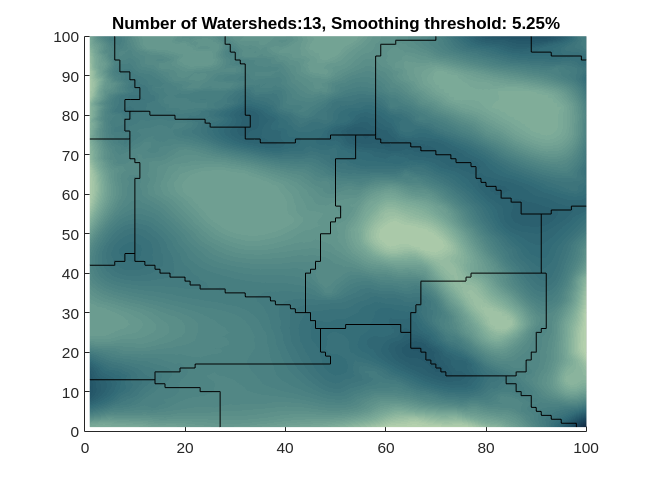

data=aoiSurfReady; % may need to change the name of input data
threshold=5.25; % percentage threshold of maxima smoothing
height=max(max(data)) - min(min(data)); 
simp_data=imhmin(-data, threshold*height/100);
aoiSurfDims = size(data);
aoiX = aoiSurfDims(2);
aoiY = aoiSurfDims(1);
clear WS watershed_lines
clf 

watershed_lines = NaN(aoiX,aoiY);
WS=watershed(simp_data); 
watershed_mask = WS==0;
watershed_lines(watershed_mask==1)= -simp_data(watershed_mask==1); 
surf(-simp_data, 'EdgeColor', 'none', 'FaceColor', 'interp')
colormap(cmap)
hold on
surf(watershed_lines, 'EdgeColor', "black")
view(2) 
title(['Number of Watersheds:', num2str(max(max(WS))), ', Smoothing threshold: ', num2str(threshold), '%' ])